##                                                       Robótica - Lista de Exercícios 1

**                        Nome: **Marcos Carvalho Ferreira                                                                            **Matrícula:** 202010203

import RoboticaBiblioteca.*

printListaManipuladores()

--------------------> Lista de Manipuladores <-----------------------
1 - Manipulador Cartesiano: PPP
   1.1 - Manipulador Pórtico: cartesianos, mas com base em suportes
2 - Manipulador Cilíndrico: RPP
3 - Manipulador Articulados/Antropomórficos: RRR
4 - Manipulador Esféricos/Polares: RRP
5 - Manipulador SCARA: RRP, diferente do esférico, tem três eixos z0,
                       z1 e z2 todos verticais e paralelos


**Questão 1**

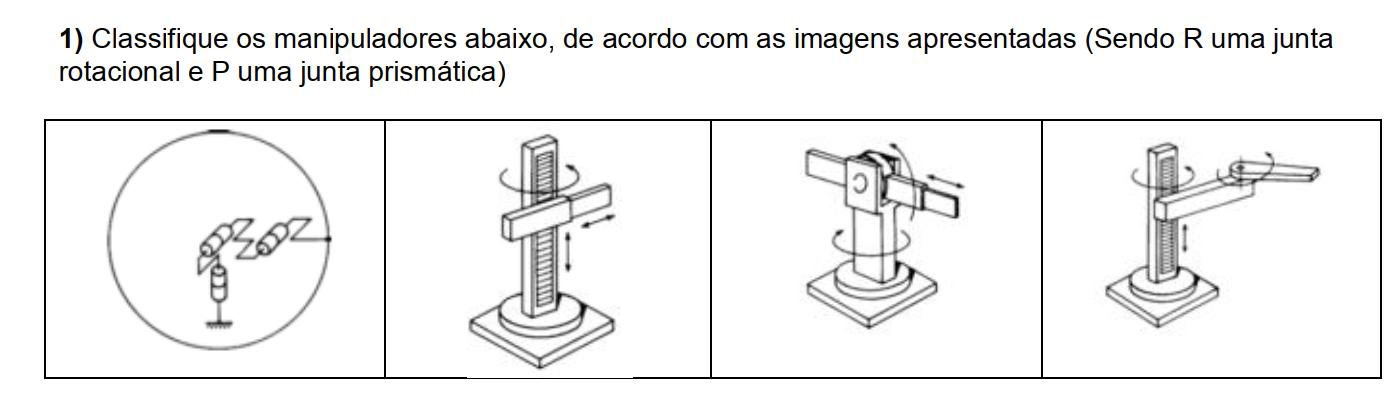

                     RRR                                 RPP                                 RRP                             PRR

**Questão 2**

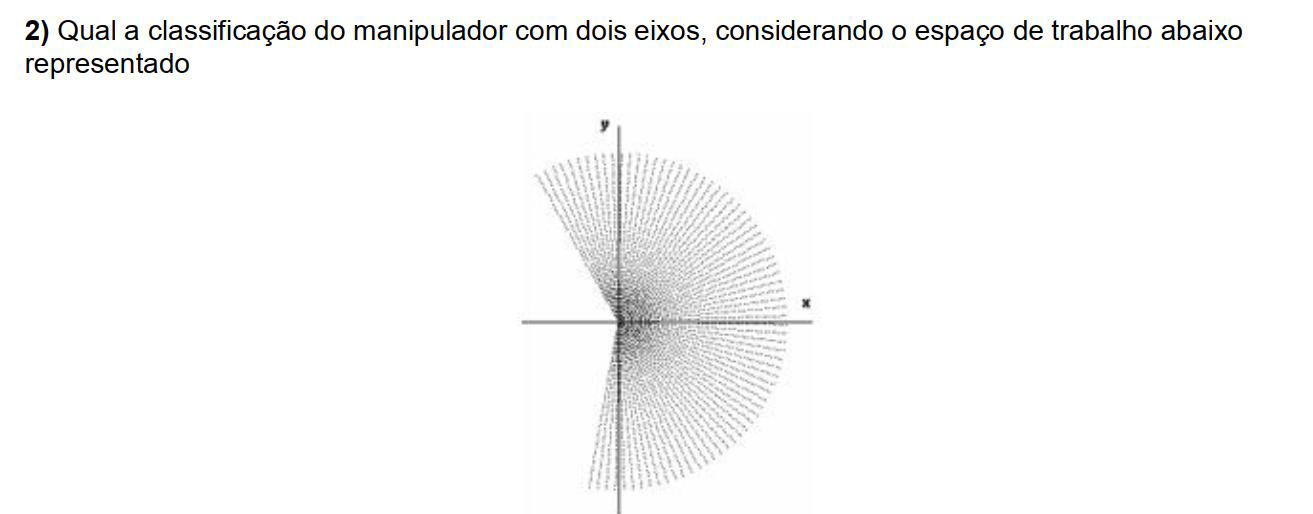

                                                                                RP

**Questão 3**

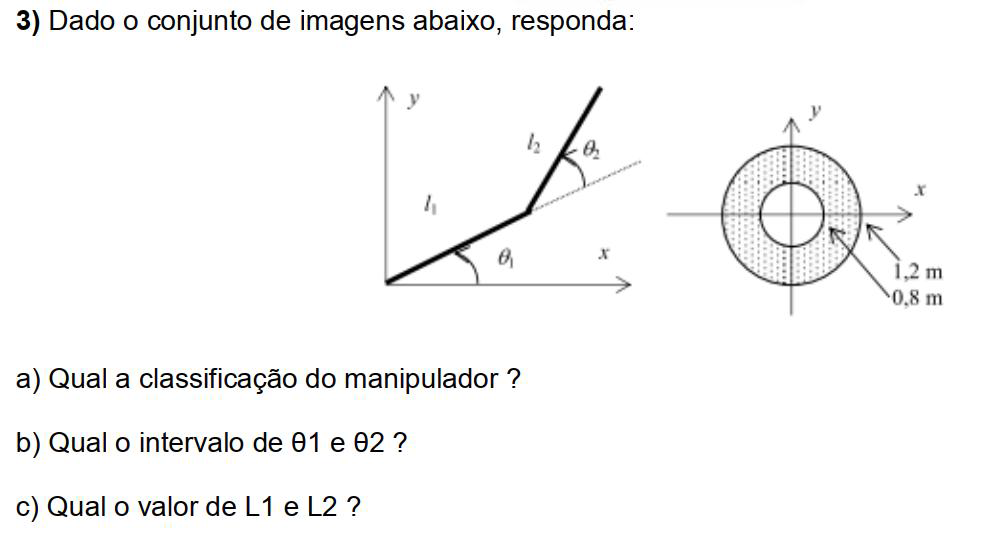

**a)   RR**

**b e c)   L1 + L2 = 1,2m**

**             L1 - L2 = 0,8m**

**            ----------------------**

**             2L1 + 0 = 2,0m**

**                L1 = 1,0m**

**            1,0 + L2 = 1,2  ---> L2 = 0,2m**

                $\theta_1 =360\degree$               ou             $\theta_1 =360\degree$

                
$$\theta_2 =360\degree$$
                                
$$\theta_2 =180\degree$$


**Questão 4**

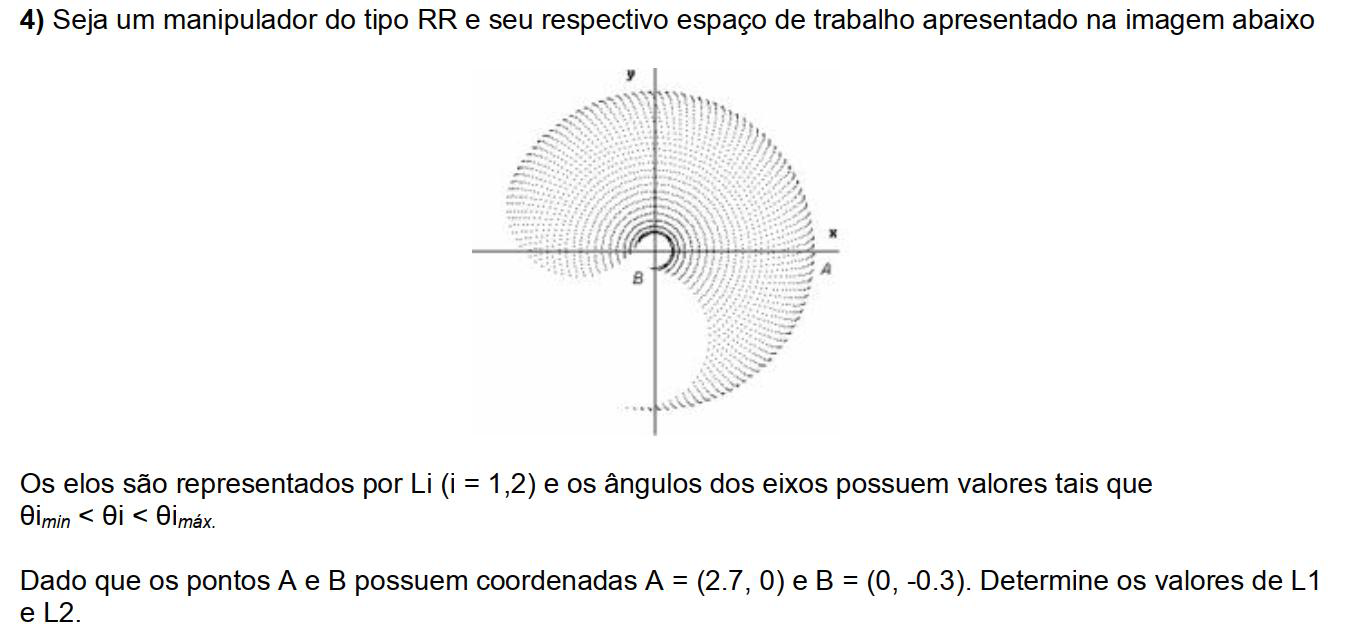

L1 + L2 = 2,7

L1 - L2 = 0,3

------------------

2*L1 + 0 = 3,0

L1 = 1,5   --->   1,5 + L2 = 2,7   ---> L2 = 1,2

**Questão 5**

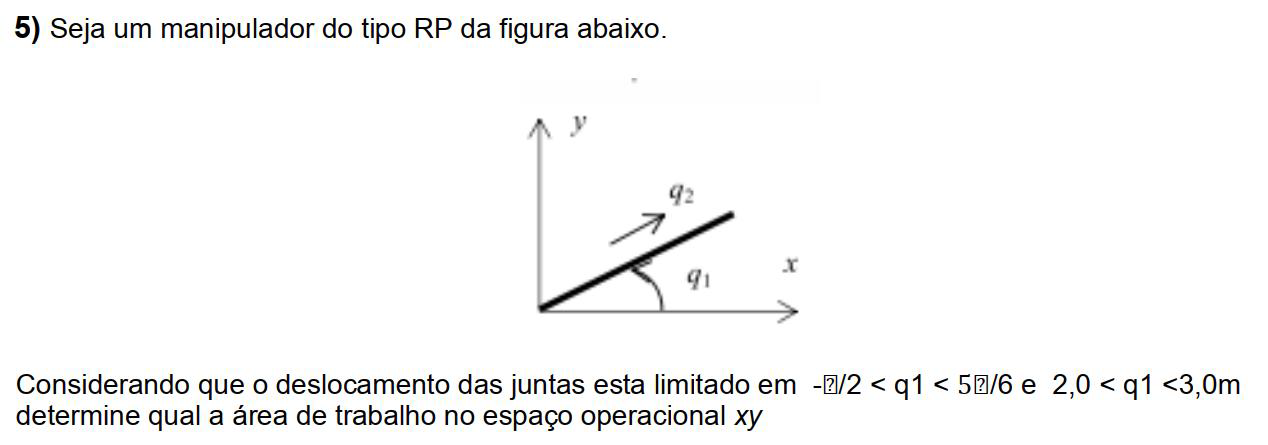

$-\frac{\pi }{2}<\textrm{q1}<\frac{5\pi }{6}$  e  $2,0<\textrm{q2}<3,0m$

r --> raio

r = (3 - 2)


$$\frac{\pi \textrm{r²}}{2}\;+\;\frac{\pi \textrm{r²}}{6}\;\to \;\frac{\pi \left(3²-2²\right)}{2}\;+\;\frac{\pi \left(3²-2²\right)}{6}\;=10,47$$


**Questão 6**

Execute o código abaixo e com base nos gráficos gerados descreve a seqüência de movimentos realizadas

% 1) Rotation about current x-axis
%theta = pi/2, R01 = rotx(theta)
%figure(1), trplot(R01, 'color', [0 0 1], 'frame', '1'),
%hold on
%figure(2), tranimate(R01), pause;
% 2) Rotation about current z-axis
%phi = pi/2, R02 = R01*rotz(phi) % post-multiply!
%figure(1), trplot(R02, 'color', [0 0.5 0], 'frame', '2'),
%hold on
%figure(2), tranimate(R02), pause;
% 3) Rotation about fixed z-axis
%alpha = pi/4, R03 = rotz(alpha)*R02 % pre-multiply!
%figure(1), trplot(R03, 'color', [1 0 0], 'frame', '3'),
%hold on
%figure(2), tranimate(R03), pause;
% Rotations do not commute
%rotx(pi/2)*rotz(pi/2) - rotz(pi/2)*rotx(pi/2)

**Questão 7**

Prove que:

                                    

syms alpha theta;

R1 = matrizRot('x',alpha)*matrizRot('x',theta)

$$R1 = \begin{array}{l} \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \sigma_{1} & -\cos\left(\frac{\pi \,\alpha }{180}\right)\,\sin\left(\frac{\pi \,\theta }{180}\right)-\sin\left(\frac{\pi \,\alpha }{180}\right)\,\cos\left(\frac{\pi \,\theta }{180}\right)\\ 0 & \cos\left(\frac{\pi \,\alpha }{180}\right)\,\sin\left(\frac{\pi \,\theta }{180}\right)+\sin\left(\frac{\pi \,\alpha }{180}\right)\,\cos\left(\frac{\pi \,\theta }{180}\right) & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,\alpha }{180}\right)\,\cos\left(\frac{\pi \,\theta }{180}\right)-\sin\left(\frac{\pi \,\alpha }{180}\right)\,\sin\left(\frac{\pi \,\theta }{180}\right) \end{array}$$

% Compute simplified symbolic expression
simplifiedExpr = simplify(R1)

$$simplifiedExpr = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\frac{\pi \,\left(\alpha +\theta \right)}{180}\right) & -\sin\left(\frac{\pi \,\left(\alpha +\theta \right)}{180}\right)\\ 0 & \sin\left(\frac{\pi \,\left(\alpha +\theta \right)}{180}\right) & \cos\left(\frac{\pi \,\left(\alpha +\theta \right)}{180}\right) \end{array}\right)$$

R2 = matrizRot('x',alpha+theta)

$$R2 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\frac{\pi \,\left(\alpha +\theta \right)}{180}\right) & -\sin\left(\frac{\pi \,\left(\alpha +\theta \right)}{180}\right)\\ 0 & \sin\left(\frac{\pi \,\left(\alpha +\theta \right)}{180}\right) & \cos\left(\frac{\pi \,\left(\alpha +\theta \right)}{180}\right) \end{array}\right)$$

R1 = matrizRot('x',30)*matrizRot('x',15)

R1 =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


R2 = matrizRot('x',30+15)

R2 =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


**Questão 8**

Um referencial foi movido10 unidades ao longo do eixo y e 5 unidades ao longo do eixo z do sistema de referência. Encontre a nova localização do referencial

                                                                                         

referencial = [0.527 -0.574 0.628 5;
               0.369 0.819 0.439 3;
               -0.766 0 0.643 8;
               0 0 0 1];
referencial = trans(0,10,5)*referencial

referencial =     0.5270   -0.5740    0.6280    5.0000
    0.3690    0.8190    0.4390   13.0000
   -0.7660         0    0.6430   13.0000
         0         0         0    1.0000


**Questão 9**

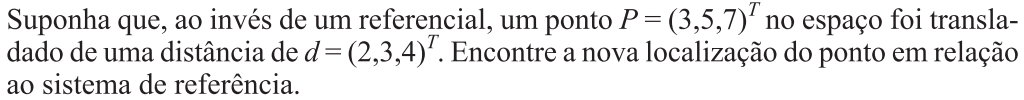

referencial = trans(3,5,7)

referencial =      1     0     0     3
     0     1     0     5
     0     0     1     7
     0     0     0     1


referencial = trans(2,3,4)*referencial

referencial =      1     0     0     5
     0     1     0     8
     0     0     1    11
     0     0     0     1


**Questão 10**

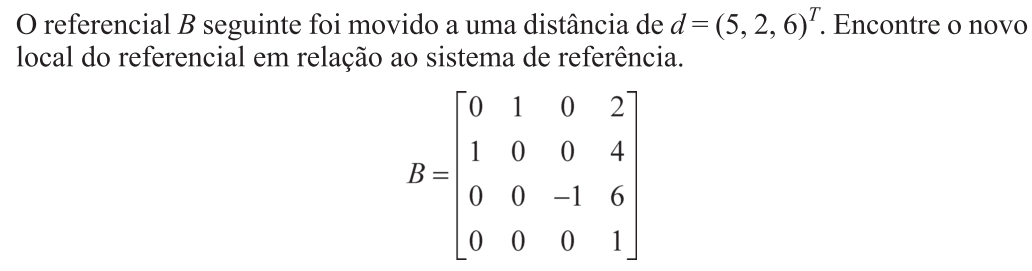

B = [0 1 0 2;
     1 0 0 4;
     0 0 -1 6;
     0 0 0 1];
B = trans(5,2,6)*B

B =      0     1     0     7
     1     0     0     6
     0     0    -1    12
     0     0     0     1


**Questão 11**

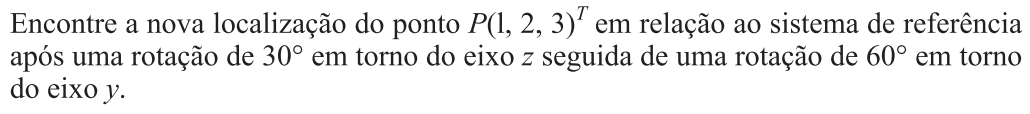

referencial = trans(1,2,3)

referencial =      1     0     0     1
     0     1     0     2
     0     0     1     3
     0     0     0     1


referencial = rot('y', 60)*rot('z', 30)*referencial

referencial =     0.4330   -0.2500    0.8660    2.5311
    0.5000    0.8660         0    2.2321
   -0.7500    0.4330    0.5000    1.6160
         0         0         0    1.0000


**Questão 12**

Um referencial B foi girado 90º em relação ao eixo x, então foi transladado em relação ao eixo atual a 3 polegadas antes de ter sido girado 90º em relação ao eixo z. Finalmente foi transladado em 5 polegadas em relação ao eixo atual o.

**a) **Escreva uma equação que descreve os movimentos

rot(z,90)*rotRot(x,90)*B*trans(0,0,3)*trans(0,5,0)

b) Encontre a posição final de um ponto p(1,5.4)T,fixado ao referencial em relação ao sistema de referencia

B = trans(1,5,4);
B = rot('z',90)*rot('x',90)*B*trans(0,0,3)*trans(0,5,0)

B =      0     0     1     7
     1     0     0     1
     0     1     0    10
     0     0     0     1


**Questão 13**

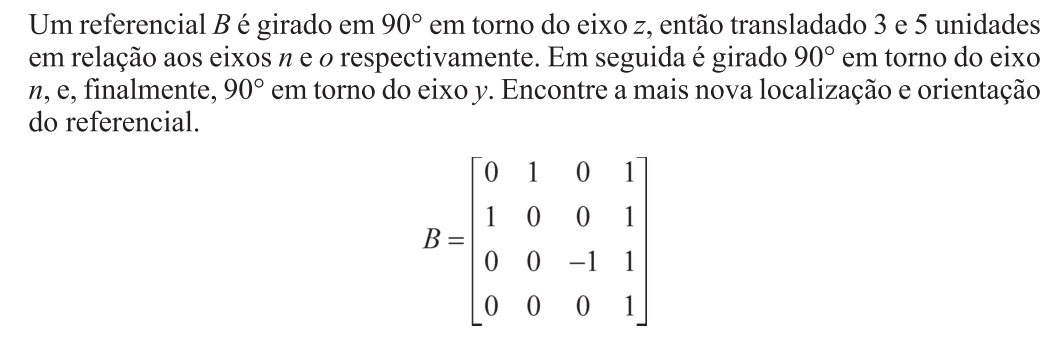

B = [0 1 0 1;
     1 0 0 1;
     0 0 -1 1;
     0 0 0 1;];
referencial = rot('y', 90)*rot('z', 90)*B*trans(3,5,0)*rot('n', 90)

referencial =      0    -1     0     1
     0     0    -1     6
     1     0     0     4
     0     0     0     1


**Questão 14**

syms theta;
matrizRotSyms('y',theta)

$$ans = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

matrizRotSyms('z',theta)

$$ans = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

**Questão 15**

Seja a célula de trabalho mostrada na figura abaixo e dados os referenciais {B} (Base), {G} (Garra}, {E} (Estação) e {O} (Objeto}; determinar GTO a partir das transformações homogêneas conhecidas BTG , BTE , ETO.

                                                                        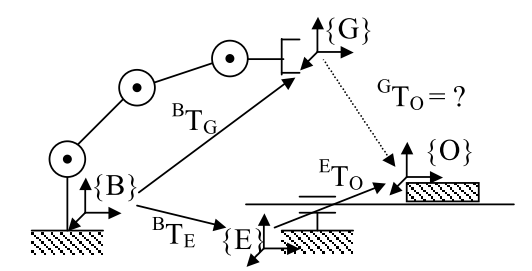

BTO = BTE * ETO

BTO = BTG * GTO

BTG * GTO = BTE * ETO

(BTG)^-1 * BTG * GTO = (BTG)^-1 * BTE * ETO

I * GTO = (BTG)^-1 * BTE * ETO

GTO = (BTG)^-1 * BTE * ETO

**Questão 16**

Suppose that three coordinate frames o1x1y1z1, o2x2y2z2 and o3x3y3z3 are given, and suppose

                                                   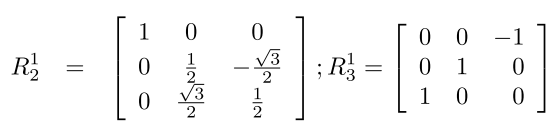

Find the matrix 𝑅32.

R12 = [1 0 0;
       0 1/2 -sqrt(3)/2;
       0 sqrt(3)/2 1/2];
R13 = [0 0 -1;
       0 1 0;
       1 0 0];

R13 = R12 * R23

(R12)^-1 * R13 = (R12)^-1 * R12 * R23   -->  (R12)^-1 * R13 = I * R23 

R23 = (R12)^-1 * R13

R23 = (R12)^-1 * R13

R23 =          0         0   -1.0000
    0.8660    0.5000         0
    0.5000   -0.8660         0
